# Collision Avoidance & Herding

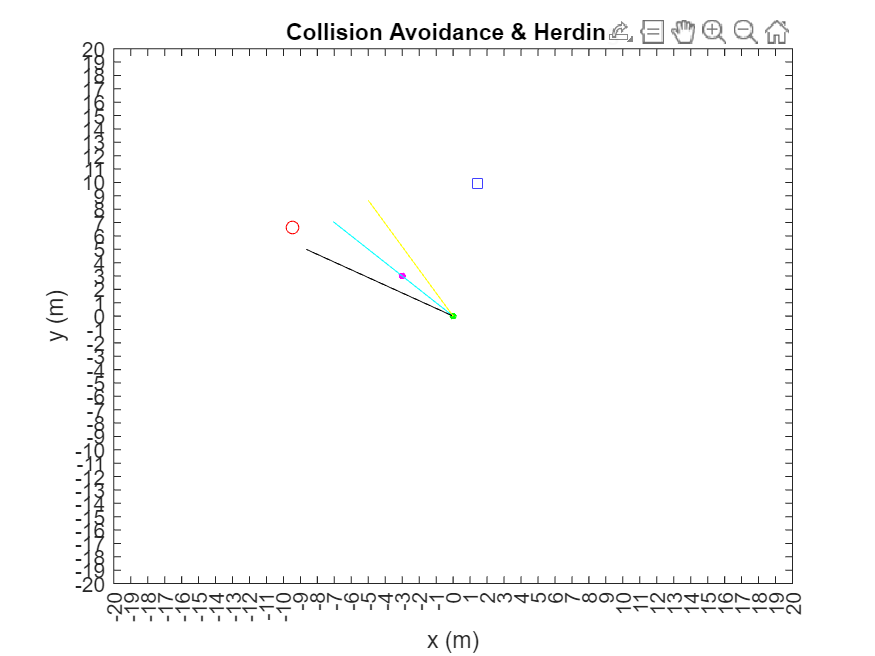

clear;clc;close;

% Position: observer_1, observer_2, GCM, C
p_1 = [-5;-4];
p_2 = @(cpt) [( 10*cos(cpt) );( 10*sin(cpt) )];
GCM = [0;0]; C = [-3;3];

% Gain & Control Law
kp = 1;
u = [0.01;0.01];
r = 0.1;

% Run Time
dt = 0.1;

% CBF
d_min = 1.5; theta_max = 40*(pi/180);
h_d = @(p1, p2) norm(p1-p2)^2 - d_min^2;
V = @(GCM, C) ((C-GCM)./norm(C-GCM));
L = @(GCM, C, p1) (((p1-C)./norm(p1-C))')*V(GCM, C);
h_theta = @(theta, GCM, C, p1) theta - acos(L(GCM, C, p1));

% QP
H = [1 0;0 1];
f = @(u) -2.*u;

% Collision & Herding
A_1 = @(p1, p2) (-2.*(p1-p2))';
A_2 = @(p1, p2, GCM, C) ((-1)/sqrt(1-L(GCM, C, p1)^2))*(V(GCM, C)./norm(p1-C) - ((((p1-C)')*V(GCM, C))./norm(p1-C)^3)'*(p1-C))';
A = @(p1, p2, GCM, C) [A_1(p1, p2);A_2(p1, p2, GCM, C)];
b = @(p1, p2, v, GCM, C, theta) [h_d(p1, p2)-2*((p1-p2)')*v;h_theta(theta, GCM, C, p1)];

% A = @(p1, p2, GCM, C) (( -1/(1-((((p1-C)./norm(p1-C))')*((C-GCM)./norm(C-GCM)))^2)^(0.5) ).*...
%                                     ( (((C-GCM)./norm(C-GCM))./norm(p1-C)) - ((((p1-C)')*((C-GCM)./norm(C-GCM)))./norm(p1-C)^3)'*(p1-C) ))';
% b = @(p1, p2, GCM, C) h_theta(GCM, C, p1);
Aeq = [];
beq = [];
lb = [];
ub = [5;5];
x0 = u;
options = optimoptions('quadprog','Display','off');

for i=1:500

    u = [0.0;0.0];
    Y = p_2(cputime);
    Y_ = p_2(cputime);
    v = (Y_-Y)/1;
    theta_max = (40-i/20)*(pi/180);

    [x,fval,exitflag,output,lambda] = quadprog(H, f(u), A(p_1, Y, GCM, C), b(p_1, Y, v, GCM, C, theta_max), Aeq, beq, lb, ub, x0, options);

    % disp(A(p_1, Y, GCM, C));
    % disp("---");
    % disp(b(p_1, Y, GCM, C));
    
    [~, col] = size(x);
    x_ = [0;0];
    if col ~= 0

        p_1 = p_1 + x*dt;
        x_ = x;
    else

        p_1 = p_1 + x_*dt;
    end

    % Configuration of Figure
    p = plot(p_1(1,1), p_1(2,1), Y(1,1), Y(2,1));
    p(1).Marker = "o";
    p(1).MarkerEdgeColor = "r";
    p(2).Marker = "s";
    p(2).MarkerEdgeColor = "b";
    viscircles([GCM(1,1) GCM(2,1)], r, "Color", "g");
    viscircles([C(1,1) C(2,1)], r, "Color", "m");

    line_t = (C-GCM)./norm(C-GCM); R = [cos(theta_max) -sin(theta_max);sin(theta_max) cos(theta_max)];
    line_l = R*line_t; R = [cos(-theta_max) -sin(-theta_max);sin(-theta_max) cos(-theta_max)];
    line_r = R*line_t;

    line([GCM(1,1), GCM(1,1)+10*line_t(1,1)], [GCM(2,1), GCM(2,1)+10*line_t(2,1)], 'Color', 'cyan');
    line([GCM(1,1), GCM(1,1)+10*line_l(1,1)], [GCM(2,1), GCM(2,1)+10*line_l(2,1)], 'Color', 'black');
    line([GCM(1,1), GCM(1,1)+10*line_r(1,1)], [GCM(2,1), GCM(2,1)+10*line_r(2,1)], 'Color', 'yellow');

    title("Collision Avoidance & Herding");
    xlabel("x (m)"); ylabel("y (m)");
    xlim([-20 20]); xticks(-20:1:20); 
    ylim([-20 20]); yticks(-20:1:20);

    drawnow;
    pause(1/1000);

    if i<500

        clf;
    end
end

# Tracking

clear;clc;close;

% Position: agent_1, agent_2
p_1 = [0;0];
p_2 = @(cpt) [( 4*cos(cpt) + sin(cpt) );( 4*sin(cpt) )];

% Gain & Control Law
kp = 1;
u = [0.01;0.01];
r = 0.1;

% Run Time
dt = 0.1;

% CBF
d_max = 1.5;
h_d = @(p1, p2) d_max^2 - norm(p1-p2)^2;

% QP
H = [1 0;0 1];
f = @(u) -2.*u;

% Tracking
A = @(p1, p2) 2*(p1-p2)';
b = @(p1, p2, v2) h_d(p1, p2) - (2*(p1-p2)')*v2;

Aeq = [];
beq = [];
lb = [];
ub = [5;5];
x0 = u;
options = optimoptions('quadprog','Display','off');

for i=1:500

    u = [0.01;0.01];
    Y = p_2(cputime);
    Y_ = p_2(cputime);
    v = (Y_-Y)/1;
    [x,fval,exitflag,output,lambda] = quadprog(H, f(u), A(p_1, Y), b(p_1, Y, v), Aeq, beq, lb, ub, x0, options);

    % disp(A(p_1, Y, GCM, C));
    % disp("---");
    % disp(b(p_1, Y, GCM, C));
    
    [~, col] = size(x);
    x_ = [0;0];
    if col ~= 0

        p_1 = p_1 + x*dt;
        x_ = x;
    else

        p_1 = p_1 + x_*dt;
    end

    % Configuration of Figure
    p = plot(p_1(1,1), p_1(2,1), Y(1,1), Y(2,1));
    p(1).Marker = "o";
    p(1).MarkerEdgeColor = "r";
    p(2).Marker = "s";
    p(2).MarkerEdgeColor = "b";

    title("Collision Avoidance & Herding");
    xlabel("x (m)"); ylabel("y (m)");
    xlim([-10 10]); xticks(-10:1:10); 
    ylim([-10 10]); yticks(-10:1:10);

    drawnow;
    pause(1/1000);

    if i<100

        clf;
    end
end